# Verfahren 1 - Iteration

## Schritt 0:

#### y-Achse

fY_WZrad = 0;
y = 0;
Y_shift = 0;

#### z-Achse

fZ_WZrad = 0;
z = 75;

#### C-Achse

[a,b,c] = deal(0);
zWst = 50;
zWz = 1;
dirFac = -1;
f_WSTrad = zWz / zWst * dirFac;
ga = 0;

#### A-Achse

A = 0;

### Umwandlungs der kartesischen Werkzeugkoordinaten in Polarkoordinaten

poi = [-60 0 -11.4937]';

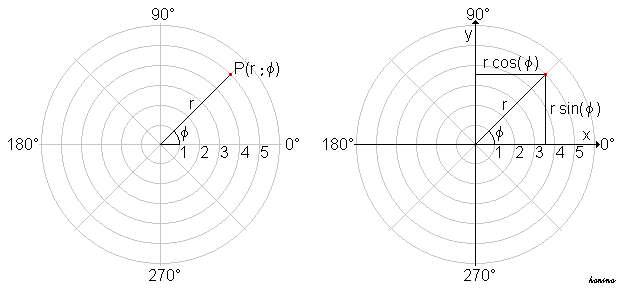

r_WZ = norm(poi(1:2));
phi_WZ = atan2(poi(2),poi(1))

phi_WZ =    3.141592653589793


h_WZ = poi(3);
% matlab function: [theta,rho,z] = cart2pol(x,y,z)

### Simulations-Setup

xMax = 75;
xMin = 15;
nSchritte = 1e2;

für jeden Iterationsschritt ein $z_{soll}$ definieren

z_soll = linspace(xMax,xMin,nSchritte);
Bsol = NaN(nSchritte,1);
iters = NaN(nSchritte,1);
error = NaN(nSchritte,1);
n = 0;      % absoluter zähler

## Schritt 1:

### Definition der Funktion

bfun = @(B,z_soll) pi - phi_WZ + asin((z - c - z_soll + B*fZ_WZrad + sin(A)*(y + Y_shift + B*fY_WZrad) + h_WZ*sin(A))./(r_WZ*cos(A)));
% bfun = @(B,z_soll) - phi_WZ - asin((z - c - z_soll + B*fZ_WZrad + sin(A)*(y + Y_shift + B*fY_WZrad) + h_WZ*sin(A))./(r_WZ*cos(A)))

## Schritt 2: Startwert für die Lösung

Startwert für B

B = 0;
B0 = pi*0.25;

#### Schritt N:

Schritt 2 mit neuem B durchführen bis Differenz zwischen B alt und B neu < gewählter Toleranz

Schleife über alle z_soll

v1T = tic;
for m = 1:nSchritte
    l = 0;  % iterationsschleifenzähler
while true
    l = l+1;
    n = n+1;

Ausgangswinkel der nächsten Iteration ist der Winkel des aktuellen Schrittes

    B0= B;
    B=  bfun(B0,z_soll(m));
    e = sum(abs(B-B0));     % error
    if e < 1e-3
        Bsol(m) = B;
        iters(m) = l;
        break
    else
        error(m) = e;
    end
end

- Alternativ: nach Schritt 2:  mit fzero lösen 0 == Z - c + B*fZ_WZrad + sin(A)*(Y + Y_shift + B*fY_WZrad) + h_WZ*sin(A) + r_WZ*cos(A)*(sin(B + phi_WZ))-Z_soll nach B 

end

## Ausgabe

fprintf('Dauer Lösung durch Iteration: %.4f sec.\n',toc(v1T))

Dauer Lösung durch Iteration: 0.0120 sec.
